# Optimization and Data Analytics HW6

## An Introduction to Optimization sec. 12

## Exercise 12.2

The initial measurements visualized:

L1 = 3; L2 = 4; L3 = 5;
L = [L1 L2 L3];
F1 = 1; F2 = 2; F3 = 4;
F = [F1 F2 F3];
figure(1)
plot(F,L,'--o')
xlim([0 5])
ylim([0 6])
hold on

Hooke's law states that the length of the spring is related to the applied force by:


$$L=a+\mathrm{bF}$$


This can be approximated by a linear straight line fit given by the expression:


$$\mathrm{Ax}=b$$


The best straight line fit is then the one that minimizes:


$${\left\|\mathrm{Ax}-b\right\|}^2$$


This system of equations can then be written as:


$$A=\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 2\\
1 & 4
\end{array}\right\rbrack ,\;x=\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack ,\;b=\left\lbrack \begin{array}{c}
3\\
4\\
5
\end{array}\right\rbrack$$


A = [1 F1; 1 F2; 1 F3]

A =      1     1
     1     2
     1     4


b = [L1; L2; L3]

b =      3
     4
     5


The least-squares estimate for *a *and *b* is then given by:


$$x^\ast  =\left\lbrack \begin{array}{c}
a^\ast  \\
b^\ast  
\end{array}\right\rbrack ={\left(A^T A\right)}^{-1} A^T b$$


x = (A'*A)^-1*A'*b

x =     2.5000
    0.6429


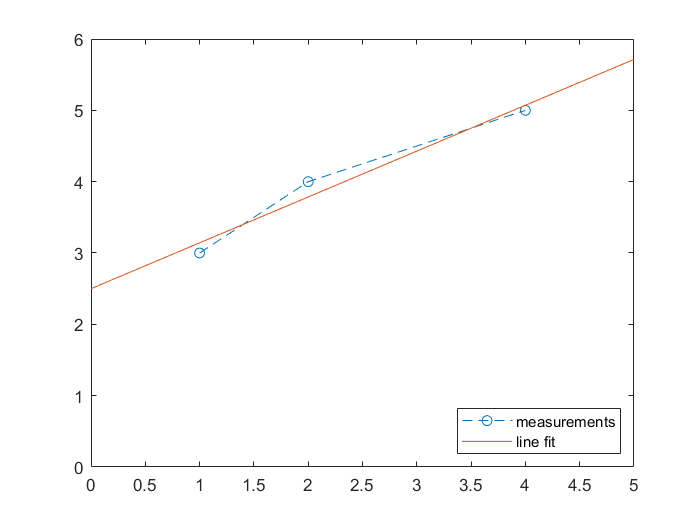

a = x(1);
b = x(2);
L_est = @(F) a+b*F;
fplot(L_est);
legend('measurements','line fit','Location','southeast')
hold off

## Exercise 12.4

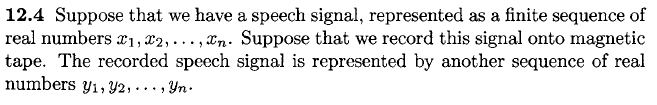

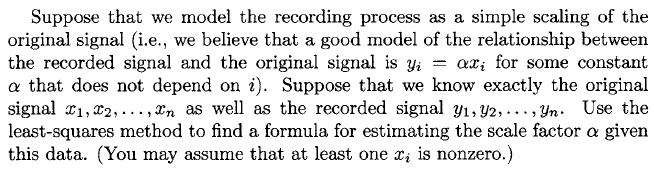

The speech signal is given by:


$$\mathbf{x}={\left\lbrack \begin{array}{c}
x_1  & x_2  & \ldotp \ldotp \ldotp  & x_n 
\end{array}\right\rbrack }^T$$


The recorded signal is given by:


$$\mathbf{y}={\left\lbrack \begin{array}{c}
y_1  & y_2  & \ldotp \ldotp \ldotp  & y_n 
\end{array}\right\rbrack }^T$$


The relationship between **x **and **y** may be modelled as:


$$y_i =\alpha x_i$$


Written in the standard linear straight line form:


$$\mathrm{Ax}=b$$



$$A=\mathbf{x},\text{\,}\text{\,}x=\alpha ,\text{\,}b=\mathbf{y}$$


The least-squares approach is then minimizing:


$${\left\|\mathrm{Ax}-b\right\|}^2$$


The least-squares estimate for $\alpha$is then given by:


$$x={\left(A^T A\right)}^{-1} A^T b\Longrightarrow \alpha ={\left({\mathbf{x}}^T \mathbf{x}\right)}^{-1} {\mathbf{x}}^T \mathbf{y}$$
